# フィット概要

・説明変数3つ  (拡散係数**D、**濃度**C**、観察体積の横方向サイズ（＝beam waist)** w0**)

→目的変数 **G(ξ, τ)**を得る 

・モデル式は　one-component diffusion (p.202)

①データの準備

・自己相関関数を用意。tableを作成する

[tau, cor]

dataframe = table((TAU)', (COR)');

### 1拡散成分のモデル式　one-component diffusion (p.202) 

beta0 = [diffusion_time , N]

b(1):diffusion_time [s]   

b(2):N

x(:,1) = tau 

SP = 7;
beta0 = [10^-3, 0.01]

beta0 =     0.0010    0.0100



modelfun_3dim_temporal = @(b, x) 1+ b(2)^(-1) .* (1 + x./ b(1)).^(-1) .* (1 + x./ (b(1).*SP^2)).^(-0.5);

②非線形モデルをデータに当てはめる

[`mdl`](https://jp.mathworks.com/help/stats/fitnlm.html#bt1hbn6-mdl) `= fitnlm(`[`tbl`](https://jp.mathworks.com/help/stats/fitnlm.html#bt1hbn6_sep_shared-tbl)`,`[`modelfun`](https://jp.mathworks.com/help/stats/fitnlm.html#shared-modelfun)`,`[`beta0`](https://jp.mathworks.com/help/stats/fitnlm.html#shared-beta0)`)` は、`modelfun` で指定されたモデルをテーブルまたはデータセット配列 `tbl` 内の変数に近似し、非線形モデル `mdl` を返します。

`(`[`mdl`](https://www.mathworks.com/help/releases/R2019b/stats/fitnlm.html?doclanguage=ja-JP&nocookie=true&prodfilter=ML%20VP%20NN%20IP%20MG%20SG%20ST%20WA&docviewer=helpbrowser&docrelease=R2019b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DYA2DUK&browser=F1help&container=jshelpbrowser#bt1hbn6-mdl?browser=F1help) `= fitnlm(x(説明変数),`[`y`](https://www.mathworks.com/help/releases/R2019b/stats/fitnlm.html?doclanguage=ja-JP&nocookie=true&prodfilter=ML%20VP%20NN%20IP%20MG%20SG%20ST%20WA&docviewer=helpbrowser&docrelease=R2019b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DYA2DUK&browser=F1help&container=jshelpbrowser#d117e377697)`（目的変数）,`[`modelfun`](https://www.mathworks.com/help/releases/R2019b/stats/fitnlm.html?doclanguage=ja-JP&nocookie=true&prodfilter=ML%20VP%20NN%20IP%20MG%20SG%20ST%20WA&docviewer=helpbrowser&docrelease=R2019b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DYA2DUK&browser=F1help&container=jshelpbrowser#bt1hbn6_sep_shared-modelfun?browser=F1help)`,`[`beta0`](https://www.mathworks.com/help/releases/R2019b/stats/fitnlm.html?doclanguage=ja-JP&nocookie=true&prodfilter=ML%20VP%20NN%20IP%20MG%20SG%20ST%20WA&docviewer=helpbrowser&docrelease=R2019b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DYA2DUK&browser=F1help&container=jshelpbrowser#bt1hbn6_sep_shared-beta0?browser=F1help)`)` は、列ベクトル `y` を応答変数として、行列 `X` の列を予測子変数として使用)

mdl = fitnlm(dataframe, modelfun_3dim_temporal, beta0)

mdl = 非線形回帰モデル: 
    Var2 ~ 1 + b2^( - 1)*(1 + x/b1)^( - 1)*(1 + x/(b1*SP^2))^( - 0.5)

推定された係数: 
          Estimate         SE        tStat       pValue  
          _________    __________    ______    __________

    b1    0.0015233    7.6888e-05    19.812    4.7988e-36
    b2      0.67226      0.017959    37.434    7.4322e-60


観測数: 100、誤差の自由度: 98
平方根平均二乗誤差: 0.0392
決定係数: 0.984、自由度調整済み決定係数 0.984
F 統計量とゼロ モデルの比較: 6.14e+04、p 値 は 1.47e-152 です

③得られた係数

parms = (mdl.Coefficients.Estimate)'

parms =     0.0015    0.6723


④プロット＆save

Before Fitting vs After Fitting

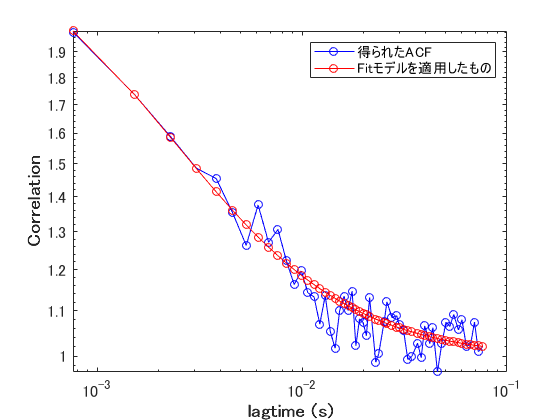

figure
original_vs_fit(TAU, COR, TAU, modelfun_3dim_temporal(parms,TAU))

%saveas(gcf,sprintf("output/0620/beforeFit_vs_afterfit/0622_%s.png", conc))

After Fitting vs ZEN

% addpath('func') 
% afterFit_vs_ZEN(tau, modelfun_1D1T(parms,tau), tau_zen, cor_zen, parms(4) ,modelfun_1D1T(parms,parms(4)))
% %saveas(gcf,sprintf("output/0620/afterfit_vs_ZEN/0622_%s.png", conc))